# RLC Circuits

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)

**Learning Goals**

- Compare the response of first and second order circuits.

- Analyze a second order RLC circuit differential equation.

- Solve for the natural frequency and damping in an RLC circuit.

- Compare underdamped, overdamped, and critically damped circuits.

## Background: RC and RL circuits

A capacitor behaves as an energy storage device. When a voltage source is applied, the capacitor charges. If the source is removed, the capacitor discharges. The time constant $\tau = RC$ characterizes the charging and discharging rate in the series RC circuit. The behavior of the RC circuit is discussed in detail in [RCCircuits.mlx](matlab: edit RCCircuits).

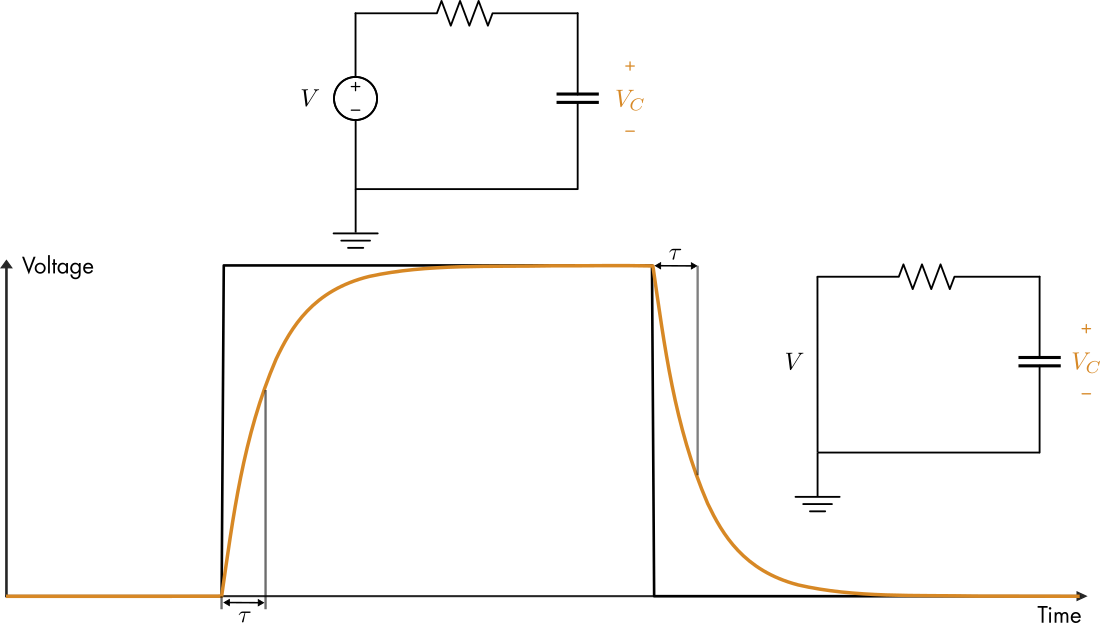

*Illustration of capacitor charging and discharging. Notice that the y-axis shows the voltage.*

An inductor also acts as an energy storage device – storing energy in an induced magnetic field. This is different from a capacitor, which stores energy in an electric field. The charging behavior of an inductor is analogous but distinct from that of a capacitor. When a *capacitor* charges, the voltage increases, and the current (which is initially large) diminishes. The opposite is true in an *inductor*: the current increases while the inductor charges until it reaches a maximum current (the current in the circuit if the inductor is short-circuited). Simultaneously, the voltage across the inductor drops exponentially from the supply voltage to zero. 

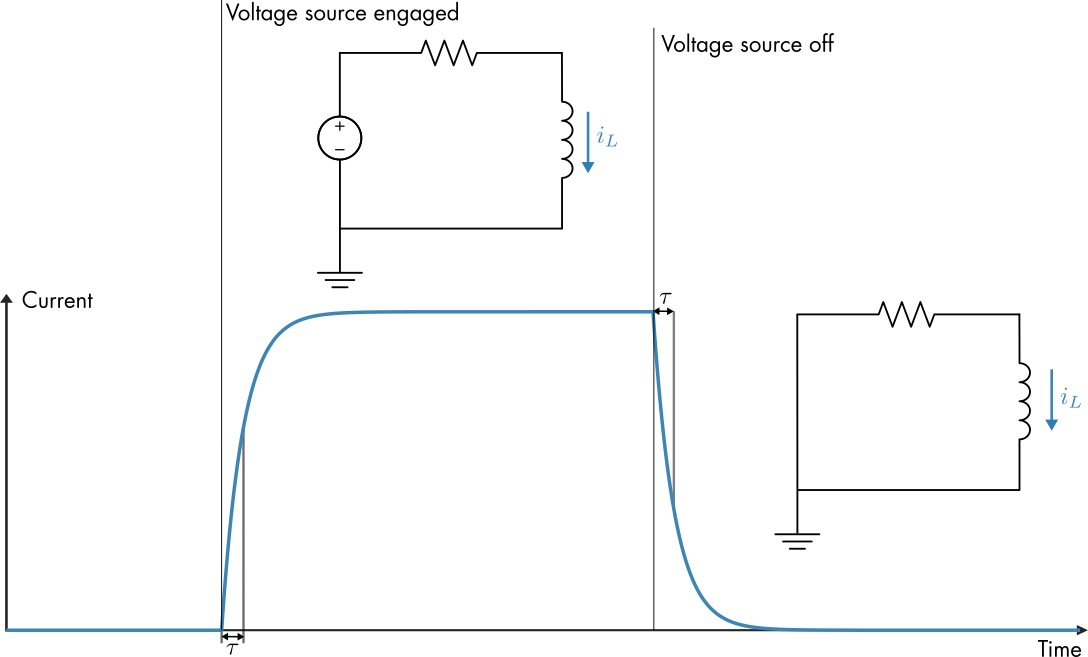

*Illustration of an inductor charging and discharging. Notice that the y-axis now shows current. *

  **Activity. **The behavior of switched RC and RL circuits are simulated in 

[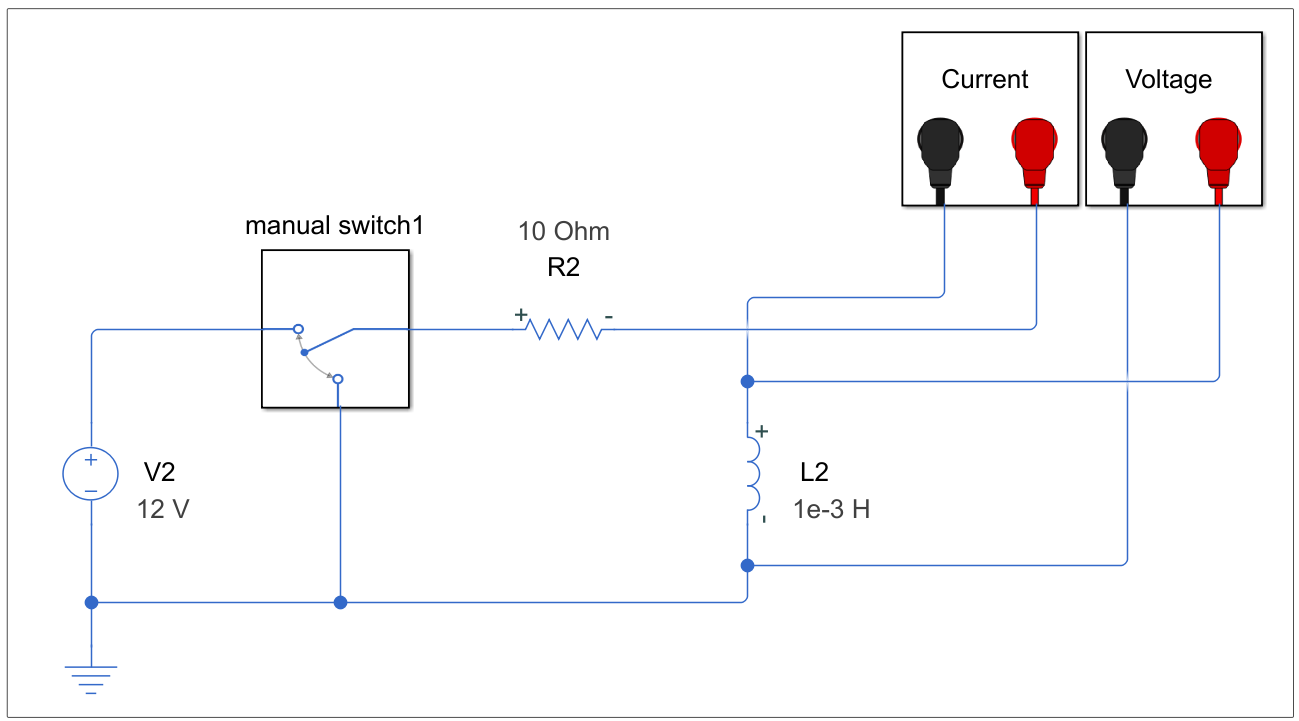](matlab: RCRLCircuits)

[`RCRLCircuits.slx`](matlab: RCRLCircuits)

Open the model and follow the instructions in the model canvas to complete the activity.

## Introduction

Both RL and RC circuits display *first order *behavior, so-called because the circuits follow solutions to first order differential equations. The resulting solutions are exponential decay curves in both the charging and discharging circuits. Combine an inductor and capacitor into a single circuit, and it exhibits more complex *second order* behavior.

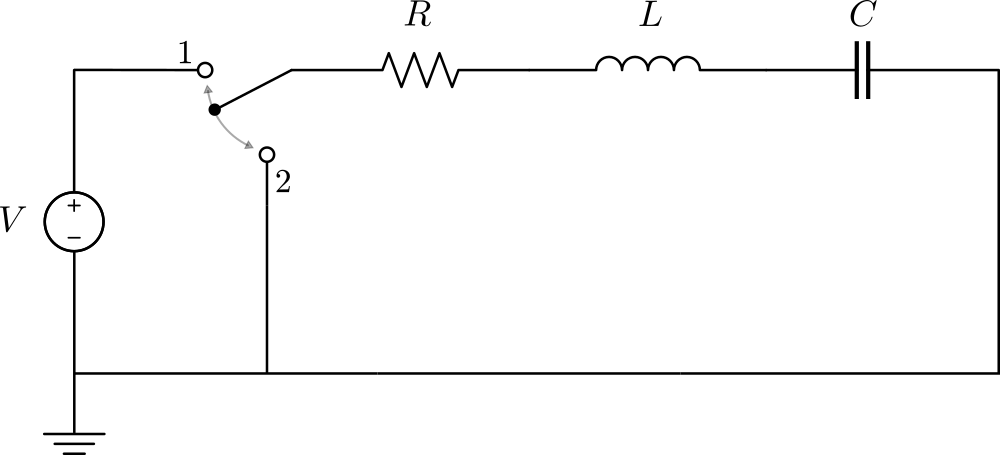

*An RLC circuit with a switch*

  **Activity. **The behavior of a switched RLC circuit is simulated in 

[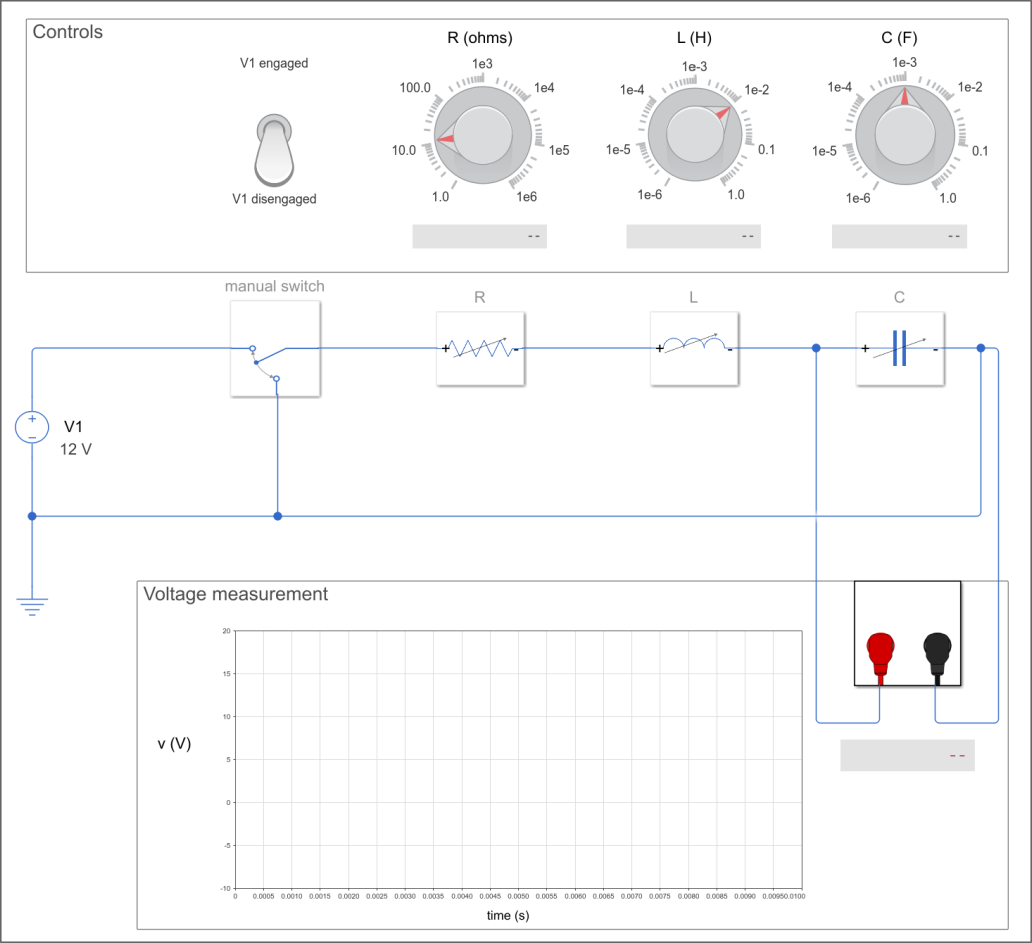](matlab: RLCCircuit)

[`RLCCircuit.slx`](matlab: RLCCircuit)

Open the model and follow the instructions in the model canvas to complete the activity.

## Discharging response

In this section, the differential equation for the discharging RLC circuit is derived and analyzed. The differential equation offers insight into the behavior of the RLC circuit. This section assumes that the circuit has been connected to the voltage source $V$ for a long time and then switched to the discharging configuration.

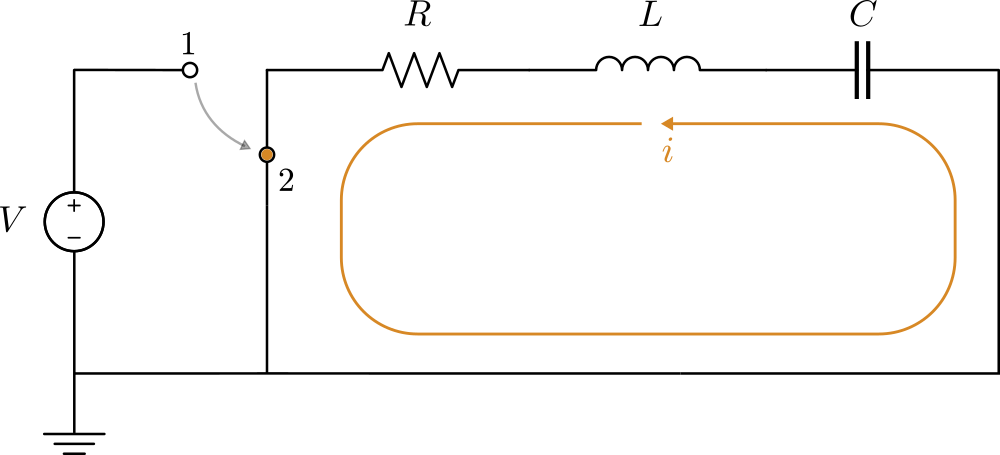

*Discharging RLC circuit*

### **Differential equation**

To derive the ODE, start by applying Kirchhoff's voltage law around the circuit:


$$V_L + V_{R} +  V_{C} = 0$$


Because the circuit is discharging, the source term is absent. Substitute the expressions for the inductor and resistor in terms of the current to find


$$ L \frac{di}{dt} +i R +  V_C = 0$$


The current is related to the voltage across the capacitor through


$$i = C \frac{dV_C}{dt} $$


The current $i$ flows through each element, so the ODE can be rewritten as


$$LC \frac{d^2 V_C}{dt^2} + RC \frac{dV_C}{dt} + V_C= 0$$


### Analysis

**General form of the ODE**

This type of second order ODE is commonly written in a general form:


$$\frac{d^2 x}{dt^2} + 2 \alpha \frac{dx}{dt} + {\omega_0}^2 x = 0$$


Rewriting the RC circuit ODE as


$$\frac{d^2 V_C}{dt^2} + 2\frac{R}{2L} \frac{dV_C}{dt} + \frac{1}{LC} V_C= 0$$


implies the constants are

 $\alpha = \frac{R}{2L}$  and  $\omega_0 = \frac{1}{\sqrt{LC}}$ 

with the general form


$$\frac{d^2 V_C}{dt^2} + 2 \alpha \frac{dV_C}{dt} + {\omega_0}^2 V_C= 0$$


This general form simplifies the analysis below.

**Solution**

To solve the ODE, you can "guess" a solution of the form


$$V_C(t) = e^{s t}$$


Plug this into the ODE to find


$$s^2 e^{st} + 2 \alpha s e^{st} + {\omega_0}^2 e^_{st} = 0$$


Factoring the expression yields


$$(s^2 + 2 \alpha s + {\omega_0}^2) e^{st} = 0$$


Because the exponential is nonzero, the quadratic must be zero:


$$s^2  + 2\alpha s + {\omega_0}^2 = 0$$


This equation is commonly referred to as the *characteristic equation*. The roots of the characteristic equation determine the behavior of the ODE solution. Using the quadratic formula shows that the solutions are


$$\begin{array}{rl}
s_{1} = - \alpha + \sqrt{ \alpha^2 - {\omega_0}^2 }
\\
s_{2} = - \alpha - \sqrt{ \alpha^2 - {\omega_0}^2 }
\end{array}$$


Because both of the characteristic roots satisfy the ODE, the solution is a linear combination of both:


$$V_c(t) = A_1 e^{s_{1} t} + A_2 e^{s_2  t}$$


Since the capacitor has been charged for a long time, the initial voltage is $V_C(0) = V$. Because the equation is second order, another initial condition is required. Assume that the voltage is not changing when the simulation starts: ${V_C}'(0) = 0$. Using these two initial conditions, you can solve for the coefficients $A_1$ and $A_2$. The resulting solution is illustrated below.

  **Activity.  **The code below solves for the coefficients $A_i$ and plots the solution for the discharging RLC circuit.

- Adjust the sliders so that the characteristic roots $s$ have only a real component. What kind of behavior is observed?

- What parameter values yield characteristic roots with an imaginary component? Refer to the expression for the roots of the characteristic equation, $s$.

- Adjust the parameters below so that the roots have an imaginary component. How does the behavior change?

% Set the parameters
R = 10; % Ohms
L = 0.0005; % Henries
C = 0.000021; % Farads
V = 12; % Volts

% Compute the characteristic roots
alpha = R/(2*L);
omega0 = 1/sqrt(L*C);
s1 = -alpha + sqrt(alpha^2 - omega0^2);
s2 = -alpha - sqrt(alpha^2 - omega0^2);

% Compute the coefficients and solution
A2 = V/(1 - s2/s1);
A1 = V - A2;
t = linspace(0,0.001,1e3);
Vc = A1*exp(s1*t) + A2*exp(s2*t);

% This code plots the result
figure("Position",[0 0 700 400])
plot(t,real(Vc),"LineWidth",1.5)
xlabel("t (s)")
ylabel("V_c (V)")
title("Discharging RLC with s_1 = " + num2str(s1,"%0.3g") + " and s_2 = " + num2str(s2,"%0.3g"),"FontWeight","normal")
axis([0 0.001 -10 25])

**Charging circuit**

The transient response of the *charging* circuit has the same form as that of the discharging circuit. The characteristic roots are identical, so the responses follow the same patterns. However, the solutions to the charging circuit are distinct from the discharging solutions due to the voltage source and initial conditions.

 **Exercise. **Derive the ODE for the *charging* circuit and solve for its characteristic roots and solutions. Plot the solutions and compare them to those of the discharging circuit.

% Write code to plot the solutions here


## Switching circuit

Manual switches are helpful for building intuition about how RC, RL, and RLC circuits work. In practice, however, the RLC circuit charging and discharging often occur in sequence in the same circuit, without a manual switch. Regular switching is generated by another circuit, typically constructed using transistors. Modeling the details of the switching elements in the circuit is not necessary for analyzing the response. 

An easy approach to modeling a switched input is to use a variable voltage source. For example, a square wave source produces the same behavior as the manual switch but at regular intervals. A variable source will be used in the remainder of this lesson, rather than a manual switch. This allows both the charging and discharging characteristics of the circuit to be viewed within the same graph.

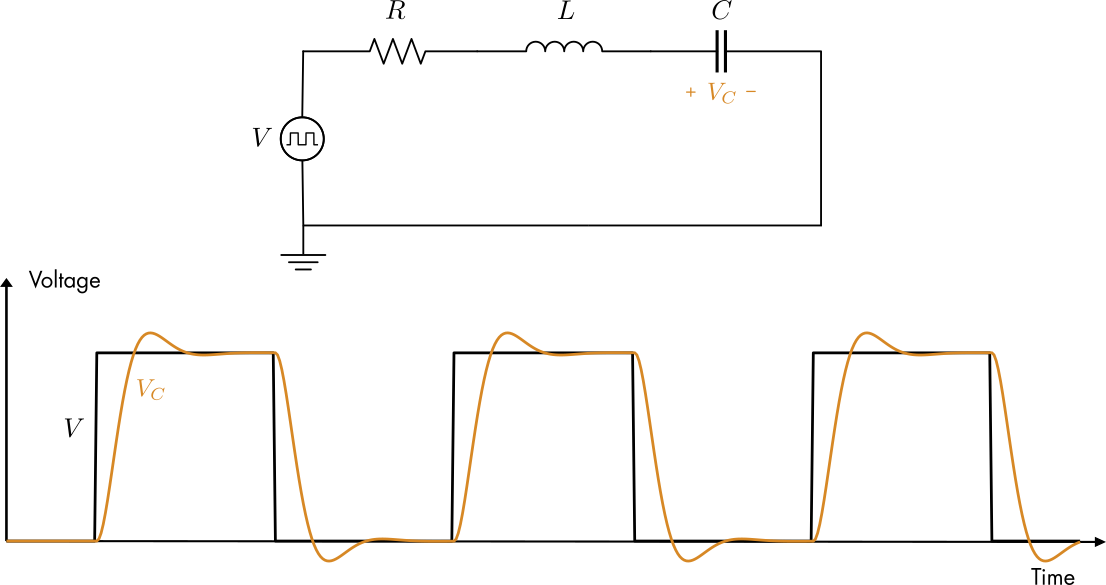

*RLC circuit with a square wave input and its response.*

  **Activity. **A signal generator and oscilloscope can be used to analyze an RLC circuit with a switched input. A virtual signal generator and oscilloscope are simulated in:

[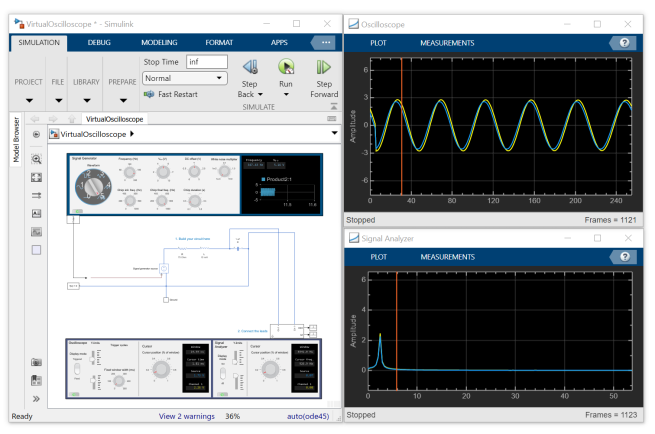](matlab: VirtualOscilloscope)

[`VirtualOscilloscope.slx`](matlab: VirtualOscilloscope)

Open the model and then perform the following to complete the activity.

    1. Connect the series RLC circuit as shown in the diagram below. Use $R = 75$$\Omega$, $L = 15$ $\text{mH}$, and $C = 1$ $\mu \text{F}$. Ensure that the source is connected to the source generator.

    2. Connect the leads of the oscilloscope to measure the voltage across the capacitor. Then, run the model.

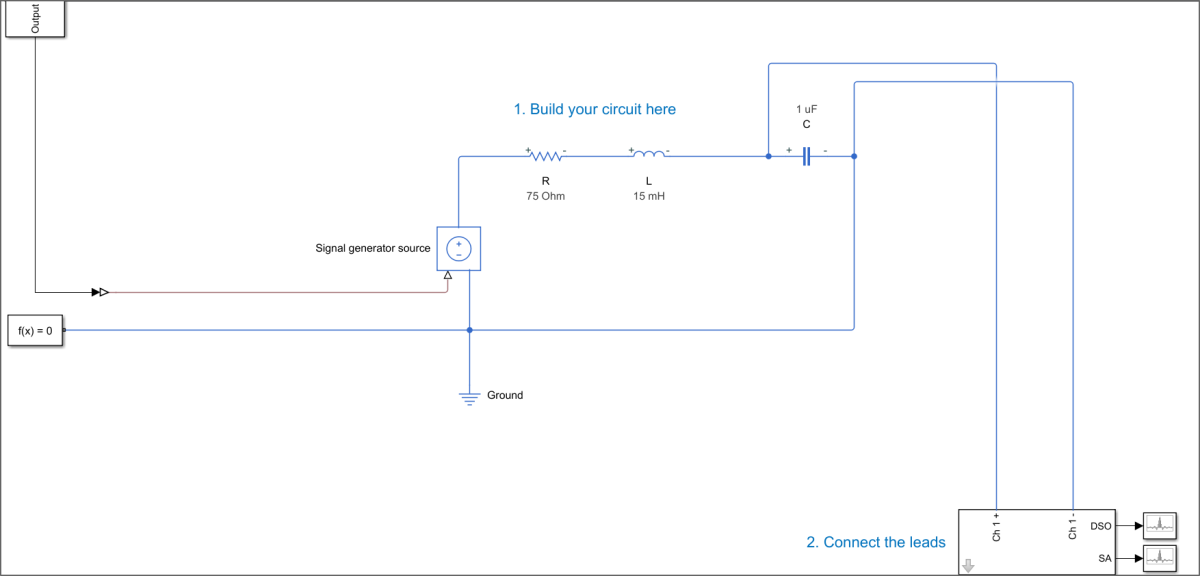

*Diagram of completed step 2: the connected circuit*

    3. Turn on the signal generator.

    4. Set the input waveform to the square wave using the dial.

    5. Set the input frequency to 200 Hz.

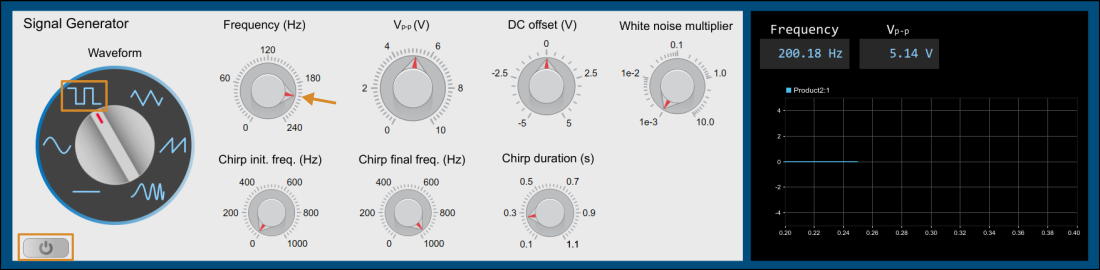

*Signal generator with the interactions for steps 3-5 highlighted.*

    6. Turn on the oscilloscope.

    7. Set the oscilloscope **Display Mode** to **Triggered** and the **Trigger cycles** to **3**.

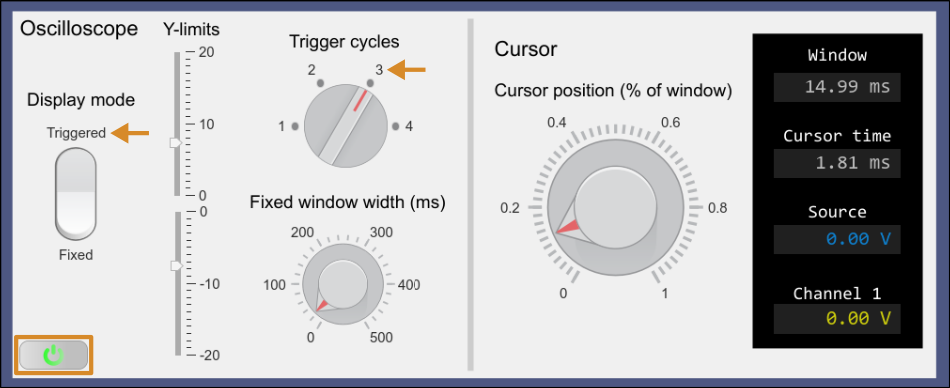

*Oscilloscope with interactions for steps 6 and 7 highlighted.*

    7. If correct, you should observe the result shown below in the Oscilloscope plot. Notice that both charging and discharging responses are visible. Based on the observed output, are the characteristic roots of this circuit real or complex?

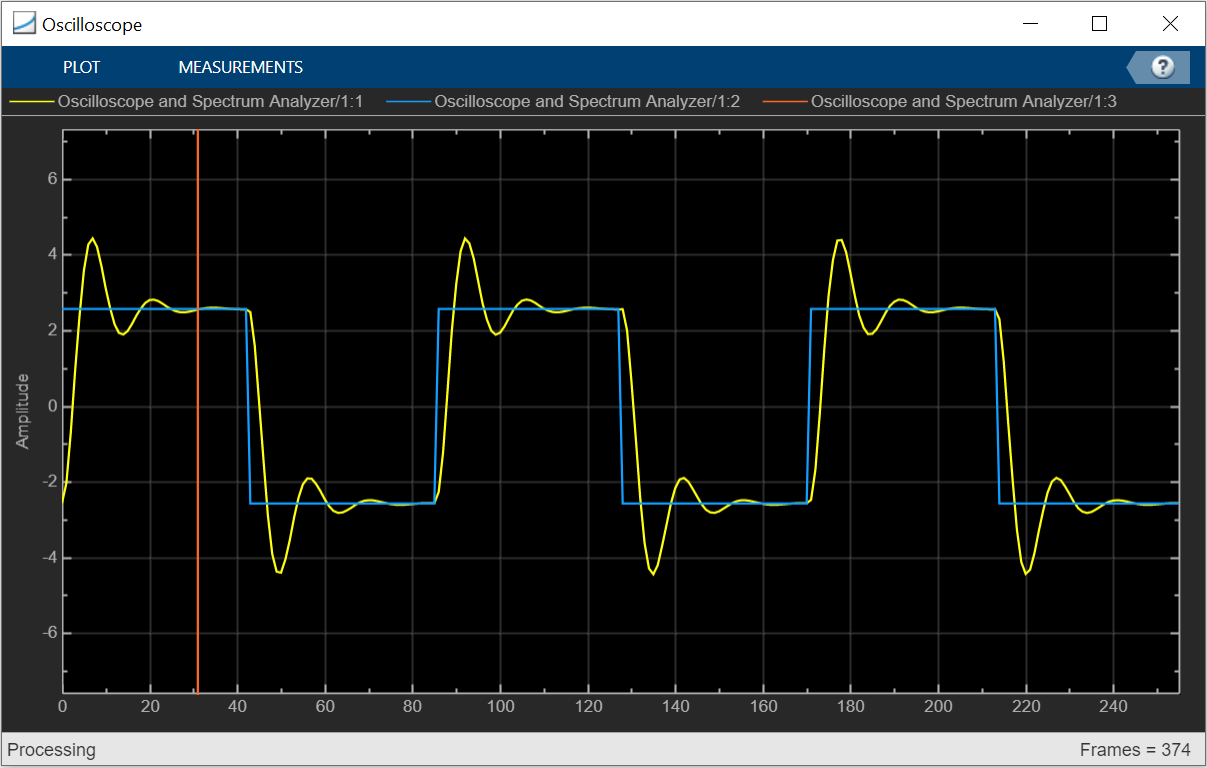

## Response classification

The transient response of the RLC circuit is characterized by two parameters:

- $\zeta = \frac{\alpha}{\omega_0}$, the *damping factor*.

- $\omega_0$, the *undamped natural frequency* or *resonant frequency*.

Recall that these parameters are defined through

$\alpha = \frac{R}{2L}$  and  $\omega_0 = \frac{1}{\sqrt{LC}}$ 

The damping factor, $\zeta$, is commonly used to classify the system. Solutions fall into three basic classifications: *overdamped*, *critically damped*, and *underdamped*.

### Overdamped

The RLC circuit is overdamped when the solutions are devoid of oscillatory behavior (the oscillations are completely "damped out"). Recall that for a complex exponential:


$$e^{(a + bi)} = e^{a} ( \cos b+  i \sin b)$$


This implies that, if the exponent is strictly real, the solution will be purely exponential: $e^a$. In this case, there will be no oscillatory behavior. In terms of the RLC circuit characteristic equation, this happens when the characteristic roots have only a real component. Recall that the characteristic roots are


$$s_{\pm} = - \alpha \pm \sqrt{ \alpha^2 - {\omega_0}^2 }$$


The roots are real if $\alpha^2 - {\omega_0}^2 \geq 0$.The system is overdamped when $\alpha^2 - \omega_0^2 > 0$. Notice that this definition excludes the edge case where $\alpha^2 - {\omega_0}^2 = 0$. In terms of the damping factor, $\zeta = \alpha / \omega_0$, the system is overdamped when $\zeta > 1$.

  **Activity. **Assume that a 10 $\mu$F capacitor and a 5 mH inductor are used in the series RLC circuit analyzed in the previous sections.

- What resistor values will produce an overdamped response? 

- What resistor value produces a damping factor $\zeta = 1.5$?

- If you have not already done so, construct a series RLC circuit and connect it as shown in the previous section. Adjust the circuit element values and measure the response of the circuit with a damping factor of 1.5 using the virtual oscilloscope:

[](matlab: VirtualOscilloscope)

[`VirtualOscilloscope.slx`](matlab: VirtualOscilloscope)

### Critically damped

The RLC circuit is critically damped when the oscillations are removed with minimal damping. In terms of the characteristic roots, $s = - \alpha \pm \sqrt{ \alpha^2 - {\omega_0}^2 }$, this occurs when 


$$\alpha^2 - {\omega_0}^2 = 0$$


In terms of the damping factor, the system is critically damped when $\zeta = 1$.

  **Activity. **Assume that a 10 $\mu$F capacitor and a 5 mH inductor are used.

- What resistor values will produce a critically damped response? 

- What resistor value produces a damping factor $\zeta = 1$?

- Adjust the circuit element values and measure the response of the circuit with a damping factor of 1 using the virtual oscilloscope, [`VirtualOscilloscope.slx`](matlab: VirtualOscilloscope).

- How does the critically damped response compare to the overdamped response you measured in the previous activity?

- Are there any oscillations present?

### Underdamped

The RLC circuit is underdamped when oscillatory behavior is present in the response. In terms of the characteristic roots, $s = - \alpha \pm \sqrt{ \alpha^2 - {\omega_0}^2 }$, this occurs when 


$$\alpha^2 - {\omega_0}^2 < 0$$


The resulting complex roots imply nonzero sine and cosine factors in the complex exponential. In terms of the damping factor, the system is underdamped when $\zeta < 1$.

  **Activity. **Assume that a 10 $\mu$F capacitor and a 5 mH inductor are used.

- What resistor values will produce an underdamped response? 

- What resistor value produces a damping factor $\zeta = 0.5$?

- Adjust the circuit element values and measure the circuit's response with a damping factor of 0.5 using the virtual oscilloscope, [`VirtualOscilloscope.slx`](matlab: VirtualOscilloscope).

- How does the underdamped response compare to the overdamped response you measured in the previous activity?

- Are there any oscillations present?

[⇦ DC Circuit Analysis Overview](matlab: OpenOverview)